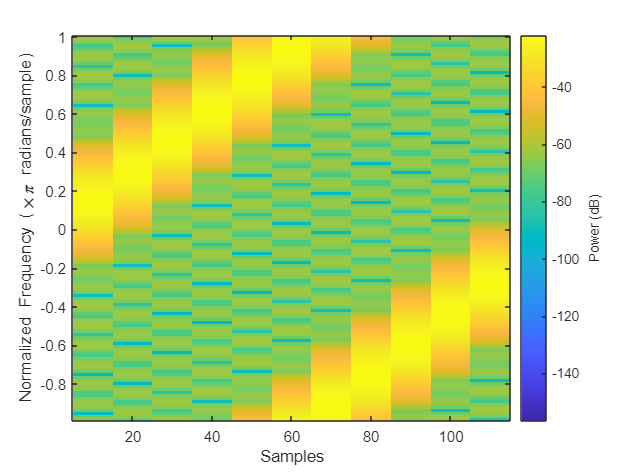

SF=7;
BW=125e3;
Fs=BW;
s=127;
SNR=-10;

%generate data symbol
num_samples = (2^SF)*Fs/BW;
k=s;
lora_symbol=zeros(1,num_samples);
for n=1:num_samples
    if k >= (2^SF)
        k=k-2^SF;
    end 
    k = k+1;
    lora_symbol(n)=(1/(sqrt(2^SF)))*exp(1i*2*pi*k*(k/(2^SF*2)));
end

spectrogram(lora_symbol,20,10,128,'power','centered', 'yaxis');

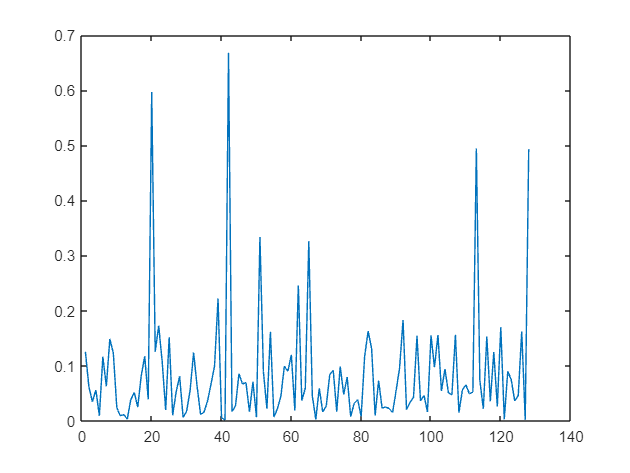


%add noise
for j = 1:100%100
    lora_symbol_noisy= awgn(lora_symbol,SNR,'measured');

    
    base_down_chirp=zeros(1,num_samples);
    k=0;
    for n=1:num_samples
        if k>= (2^SF)
            k=k-2^SF;
        end
        k=k+1;
        base_down_chirp(n)=(1/(sqrt(2^SF)))*exp(-1i*2*pi*k*(k/(2^SF*2)));
    end

    dechirped=lora_symbol_noisy.*base_down_chirp;
    corrs=(abs(fft(dechirped)).^2);
    plot(corrs)
    [~, ind]=max(corrs);
    ind2(j)=ind;
    pause(0.01)
end

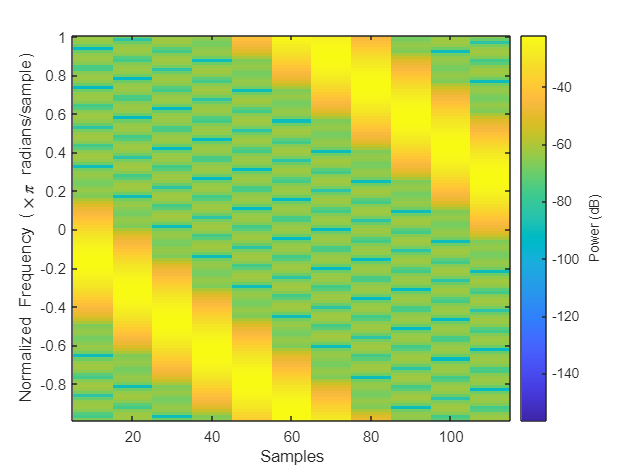


spectrogram(base_down_chirp,20,10,128,'power','centered', 'yaxis');

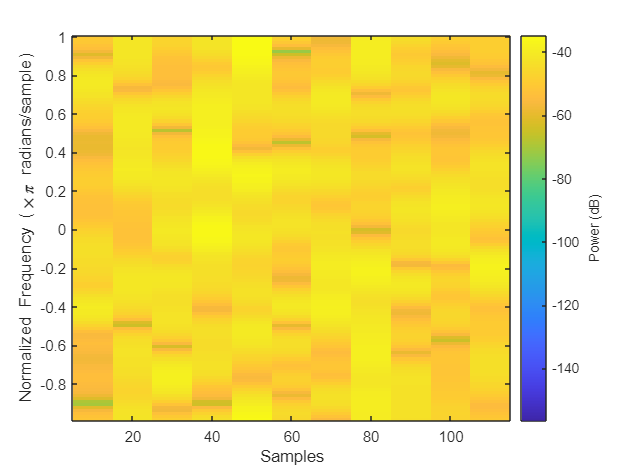

spectrogram(dechirped,20,10,128,'power','centered', 'yaxis');

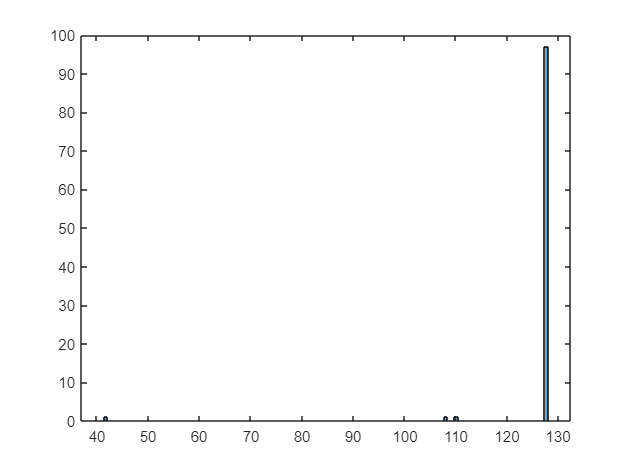


histogram(ind2,2^SF)

symbol_error_rate= sum(ind2~=s+1)/j

symbol_error_rate = 0.0300

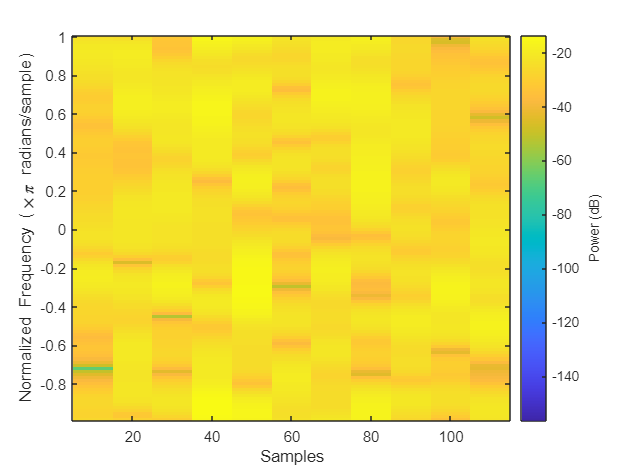


spectrogram(lora_symbol_noisy,20,10,128,'power','centered', 'yaxis');